# Homework #6: Pendulum Models

Initiate Variables

% coefficients 
m = 0.128; % kg
g = 9.81; % m/s^2
L = 0.34; % m
J = (1/3)*m*L*L; % kg m^2
b = 0.004; % Nms/rad

% initial conditions
theta_dot = 0; % rad/s
theta = deg2rad(20); % rad

Non-Linear Simulation 

% run the non-linear simulation
out = sim('Pendulum_Simulink.slx', 7);

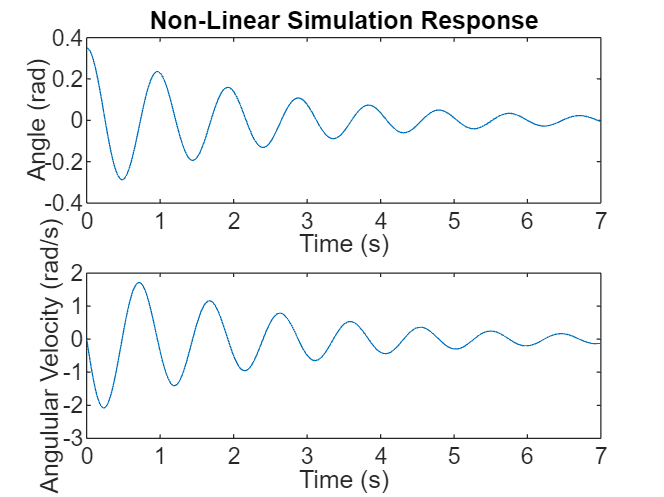

% plot response
subplot(2, 1, 1)
plot(out.theta.Time, out.theta.Data)
title("Non-Linear Simulation Response")
xlabel("Time (s)")
ylabel("Angle (rad)")

subplot(2, 1, 2)
plot(out.theta_dot.Time, out.theta_dot.Data)
xlabel("Time (s)")
ylabel("Angulular Velocity (rad/s)")

Linear Simulation

% run the linear simulation
out_linear = sim('Pendulum_Simulink_Linear.slx', 7);

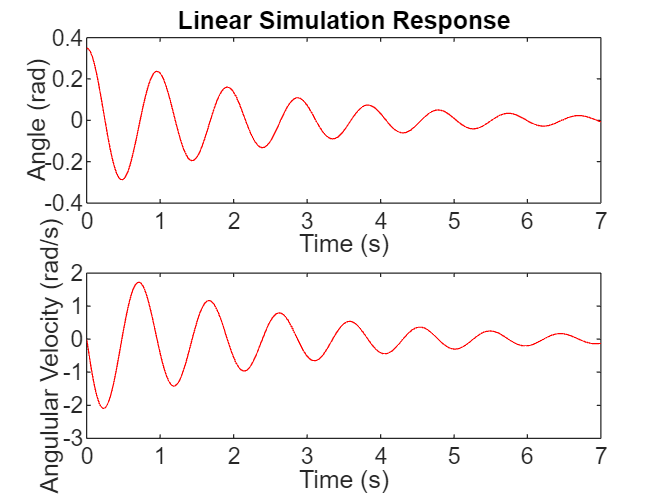

% plot response
subplot(2, 1, 1)
plot(out_linear.theta.Time, out_linear.theta.Data, 'r')
title("Linear Simulation Response")
xlabel("Time (s)")
ylabel("Angle (rad)")

subplot(2, 1, 2)
plot(out_linear.theta_dot.Time, out_linear.theta_dot.Data, 'r')
xlabel("Time (s)")
ylabel("Angulular Velocity (rad/s)")

Theoretical Natural Frequency

w_n = sqrt((m*L*g)/(2*J)) % natural frequency

w_n = 6.5787

Non-Linear Simulation

[pks, locs] = findpeaks(out.theta.Data); % find peaks 

T = mean(diff(out.theta.Time(locs))); % calculate average period of oscillation

w = (2*pi)/T % frequency of oscillation

w = 6.5631

Non-Linear Simulation

[pks, locs] = findpeaks(out_linear.theta.Data); % find peaks

T = mean(diff(out_linear.theta.Time(locs))); % calculate average period of oscillation

w = (2*pi)/T % frequency of oscillation

w = 6.5669

10 deg

theta = deg2rad(10); % rad

% run the non-linear simulation
out = sim('Pendulum_Simulink.slx', 7);

% run the linear simulation
out_linear = sim('Pendulum_Simulink_Linear.slx', 7);

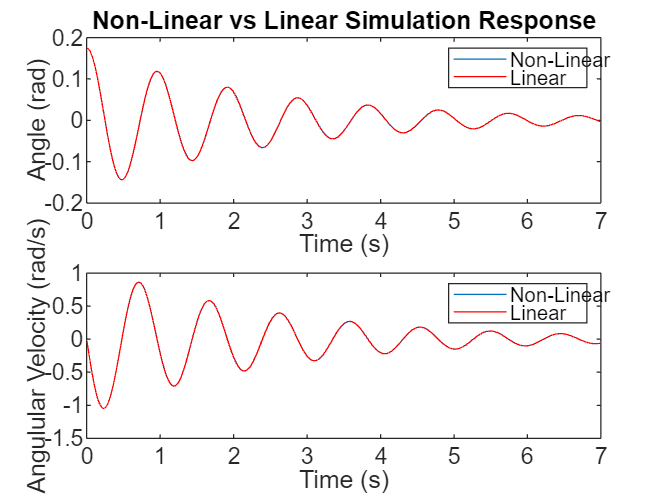

% plot response
subplot(2, 1, 1)
plot(out.theta.Time, out.theta.Data)
hold on 
plot(out_linear.theta.Time, out_linear.theta.Data, 'r')
hold off
title("Non-Linear vs Linear Simulation Response")
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Non-Linear", "Linear")

subplot(2, 1, 2)
plot(out.theta_dot.Time, out.theta_dot.Data)
hold on 
plot(out_linear.theta_dot.Time, out_linear.theta_dot.Data, 'r')
hold off
xlabel("Time (s)")
ylabel("Angulular Velocity (rad/s)")
legend("Non-Linear", "Linear")

45 deg

theta = deg2rad(45); % rad

% run the non-linear simulation
out = sim('Pendulum_Simulink.slx', 7);

% run the linear simulation
out_linear = sim('Pendulum_Simulink_Linear.slx', 7);

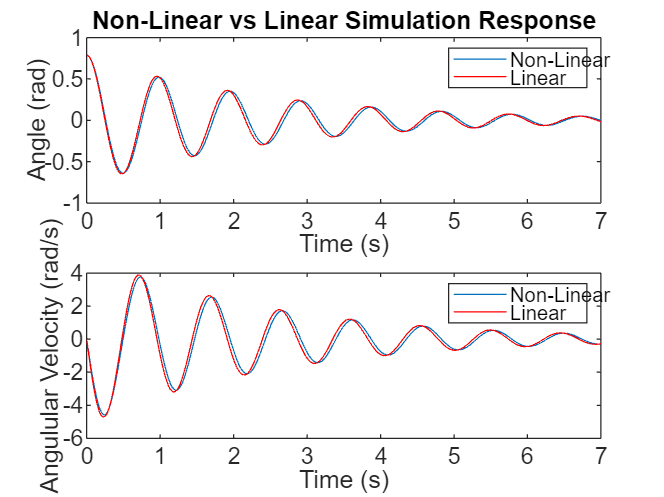

% plot response
subplot(2, 1, 1)
plot(out.theta.Time, out.theta.Data)
hold on 
plot(out_linear.theta.Time, out_linear.theta.Data, 'r')
hold off
title("Non-Linear vs Linear Simulation Response")
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Non-Linear", "Linear")

subplot(2, 1, 2)
plot(out.theta_dot.Time, out.theta_dot.Data)
hold on 
plot(out_linear.theta_dot.Time, out_linear.theta_dot.Data, 'r')
hold off
xlabel("Time (s)")
ylabel("Angulular Velocity (rad/s)")
legend("Non-Linear", "Linear")

Non-Linear Simulation

[pks, locs] = findpeaks(out.theta.Data); % find peaks 

T = mean(diff(out.theta.Time(locs))); % calculate average period of oscillation

w = (2*pi)/T % frequency of oscillation

w = 6.5527

Non-Linear Simulation

[pks, locs] = findpeaks(out_linear.theta.Data); % find peaks

T = mean(diff(out_linear.theta.Time(locs))); % calculate average period of oscillation

w = (2*pi)/T % frequency of oscillation

w = 6.5663

175 deg

theta = deg2rad(175); % rad

% run the non-linear simulation
out = sim('Pendulum_Simulink.slx', 7);

% run the linear simulation
out_linear = sim('Pendulum_Simulink_Linear.slx', 7);

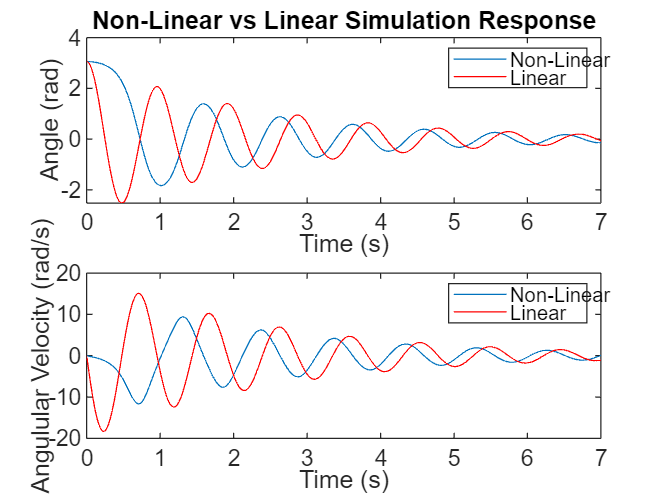

% plot response
subplot(2, 1, 1)
plot(out.theta.Time, out.theta.Data)
hold on 
plot(out_linear.theta.Time, out_linear.theta.Data, 'r')
hold off
title("Non-Linear vs Linear Simulation Response")
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Non-Linear", "Linear")

subplot(2, 1, 2)
plot(out.theta_dot.Time, out.theta_dot.Data)
hold on 
plot(out_linear.theta_dot.Time, out_linear.theta_dot.Data, 'r')
hold off
xlabel("Time (s)")
ylabel("Angulular Velocity (rad/s)")
legend("Non-Linear", "Linear")